%Taking an image
clear
rgb = acquireImage();

Dot NET assembly loaded.
1 camera was discovered.
Opening the first camera
Starting software triggered image acquisition.
Image frame number: 1
Stopping software triggered image acquisition.
Releasing the camera


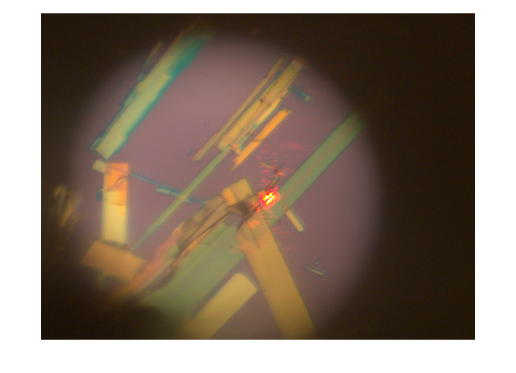

imshow(rgb);

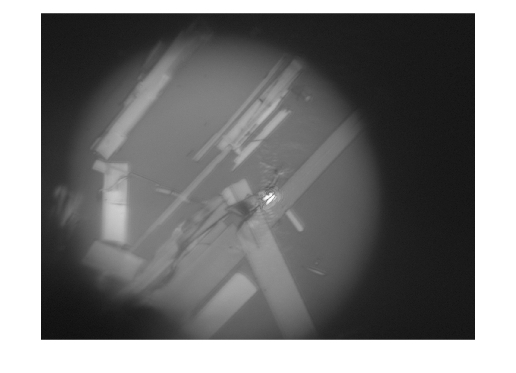

grayImage = rgb2gray(rgb);
imshow(grayImage);

%Laser is the maximum pixel value
binarized = grayImage > 0.85;
%denoise in case of outlier pixels
binarized = bwareaopen(binarized, 60);

%get coordinates of laser
object = regionprops(binarized, 'Centroid');


x = object.Centroid(1);

Intermediate dot '.' indexing produced a comma-separated list with 3 values, but it must produce a single value when followed by subsequent indexing operations.

Related documentation

y = object.Centroid(2);
imshow(binarized);
hold on;
plot(x, y, 'r.')
hold off;